clear;clc;
PATH = "/Users/nbonnie/Desktop/Lab/Videos/Frontalis_HLCSP_1min_clip.mp4";

% Single frame analysis
n_min = 20;                % Minimum number of fireflies in frame 
frame_number = 0;          % If you know the frame number you want, put it here. If 0, program will use n_min
max_frames = NaN;          % Maximum number of frames the algorithm will process looking for n_min. Set to NaN to search entire video.

% Video Processing Parameters
bwth = 0.1;                 %prm.trk.bwThr;
blurRadius = 1;             %prm.trk.blurRadiusPxl;
bkgrWinWidthSec = 2;        %prm.trk.bkgrStackSec; 

% Setup all pathing required for script
path_parts = strsplit(PATH, "/");
file_name = path_parts(end);
folder_parts = strsplit(PATH, file_name);
path_to_folder = folder_parts(1);
addpath(genpath(path_to_folder))

% Read in video
v = VideoReader(PATH);
frameRate = v.FrameRate;
disp(v)

  VideoReader with properties:

   General Properties:
            Name: 'Frontalis_HLCSP_1min_clip.mp4'
            Path: '/Users/nbonnie/Desktop/Lab/Videos'
        Duration: 38.8890
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1920
          Height: 1080
       FrameRate: 59.9401
    BitsPerPixel: 24
     VideoFormat: 'RGB24'




bkgrWinSize = bkgrWinWidthSec*frameRate;
% create background stack

frmidx = 1;
% build initial background stack
while frmidx <= bkgrWinSize
    % read frame
    frame = readFrame(v);
    
    % use only green channel
    frame = frame(:,:,2);
    
    % use single precision, for speed
    frame = single(frame);
    
    % add to background stack
    bkgrStack(:,:,frmidx) = frame;
    
    % update frame counter
    frmidx = frmidx+1;
    
end
    
% frame index within the stack
bkgrIdx = 1:bkgrWinSize;

% initial background frame
bkgr = mean(bkgrStack,3);

%% re-initialize movie since using readFrame
v = VideoReader(PATH);    
frmlocidx = 1;

% initialize waitbar
w = waitbar(0,"Processing Frames...");

frame_found = false;
if isnan(max_frames)
    max_frames = v.NumFrames;
end
nFramesApprox = min(ceil(v.NumFrames), max_frames);

% process each frame
while hasFrame(v)
    
    % read frame
    newFrame = readFrame(v);
    frame = newFrame;
    
    % use only green channel
    newFrame = newFrame(:,:,2);
    
    % use single precision, for speed
    newFrame = single(newFrame);
    
    % calculate new bkgr from old and differential earliest/latest frames (for speed) 
    [~,m] = min(bkgrIdx);
    bkgr = bkgr + (newFrame - bkgrStack(:,:,m))/bkgrWinSize;
    
    % update stack with new frame replacing earliest frame
    bkgrStack(:,:,m) = newFrame;
    bkgrIdx(m) = frmidx;
    
    % grab current frame from stack
    currentFrameIdx = frmidx;
    f = (bkgrIdx == currentFrameIdx);
    currentFrame = bkgrStack(:,:,f);     
    
    % calculate foreground
    frgr = (currentFrame - bkgr);

    f_greens = frgr;

    frgr = uint8(frgr);
    frgr = imgaussfilt(frgr,blurRadius);
    
    % binarize foreground and analyze connected components
    bw = imbinarize(frgr,bwth);
    rp = regionprops(bw,newFrame,'Centroid','Area','Eccentricity','MeanIntensity');

    n = length(rp);
    %if ((currentFrameIdx > 1607) && (n == 1))
    %if currentFrameIdx == 1815
    if frame_number == 0
        if n >= n_min
            frame_save = frame;
            greens_save = newFrame;
            frgr_save = frgr;
            bw_save = bw;
            currentFrameIdx_save = currentFrameIdx;
            frame_found = true;
        end
    elseif frame_number == currentFrameIdx
        frame_save = frame;
        greens_save = newFrame;
        frgr_save = frgr;
        bw_save = bw;
        currentFrameIdx_save = currentFrameIdx;
    end

    ff.n(currentFrameIdx) = n;
    ff.xy{currentFrameIdx} = [vertcat(rp.Centroid) repmat(currentFrameIdx,n,1)];
    ff.aei{currentFrameIdx} = [vertcat(rp.Area) vertcat(rp.Eccentricity) vertcat(rp.MeanIntensity) repmat(currentFrameIdx,n,1)];
    ff.i(currentFrameIdx) = mean(newFrame,'all'); %
    
    % progress
    try
        waitbar(frmlocidx/nFramesApprox, w, "Processing Frames...");
    catch
        continue
    end
    
    % update frame counter
    frmidx = frmidx+1;
    frmlocidx = frmlocidx+1;

    if frame_found
        close(w)
        disp("Frame found with > n flashes")
        break
    end

    if (frmidx > max_frames)
        close(w)
        error("Max frames hit, did not find a frame with > n flashes. Rerun with a lower n_min value or higher max_frames value")
        break    %#ok
    end
end

Frame found with > n flashes


## Plots of frame

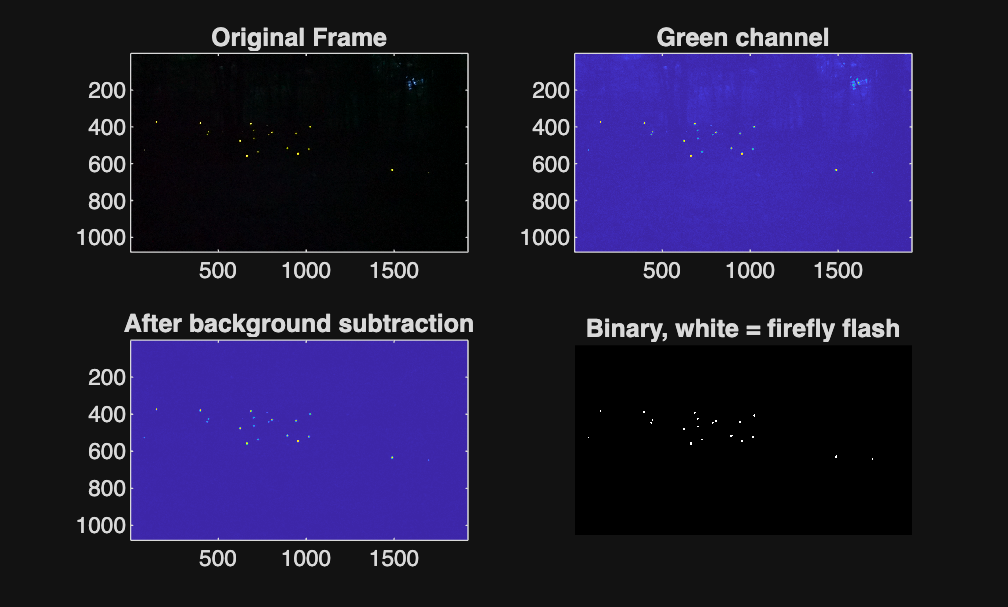

clf;
warning('off', 'images:im2bw:binaryInput');
figure();
%frame
subplot(2,2,1)
image(frame_save)
title("Original Frame")
%new_frame_save
subplot(2,2,2)
image(greens_save)
title("Green channel")
%background subtraction
subplot(2,2,3)
image(frgr_save)
title("After background subtraction")
%binary
subplot(2,2,4)
im2bw(bw_save) %#ok
title("Binary, white = firefly flash")

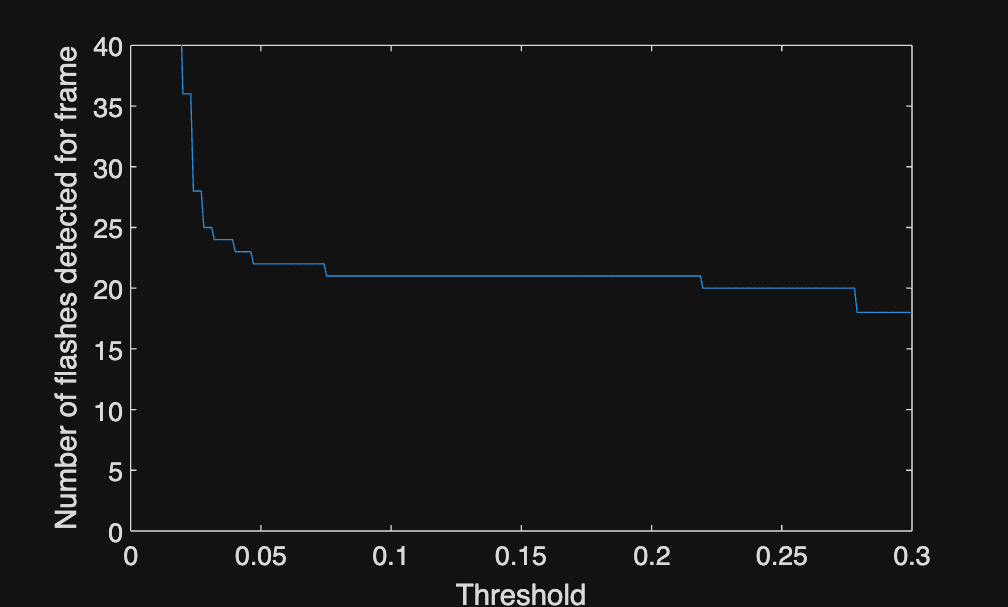

%% Elbow plot

% Analyzing effect of threshold sensitivity on 
clf; hold off;
thresholds = linspace(0,0.3,300);
detected_flashes = zeros(1,length(thresholds));
n = length(thresholds);

w = waitbar(0,"Calculating Elbow Plot...");

i = 1;
for thrs = thresholds
    rp_temp = regionprops(imbinarize(imgaussfilt(frgr_save,1),thrs), greens_save, 'Centroid','Area','Eccentricity','MeanIntensity');
    detected_flashes(i) = length([rp_temp.Area]);
    i = i + 1;
    try
        waitbar(i/n, w, "Calculating Elbow Plot...");
    catch
        continue
    end
end
close(w)

plot(thresholds, detected_flashes);
ylim([0,40])
ylabel("Number of flashes detected for frame");
xlabel("Threshold");

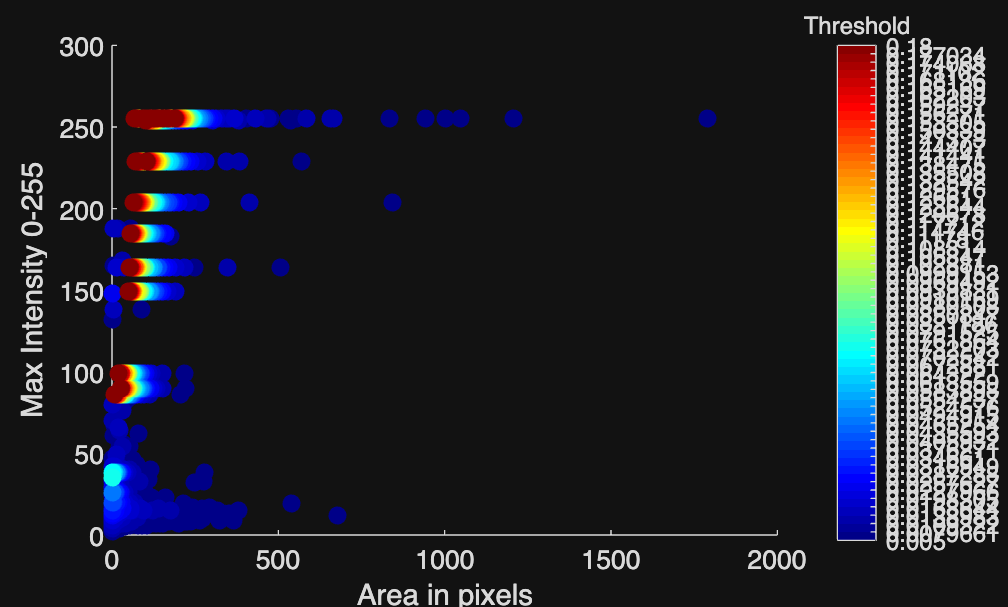

%% % Plotting across a range of bandwidths
clf; hold on;
thresholds = linspace(0.005, 0.18, 60);
cm = jet(length(thresholds));
colormap(cm);

for i = 1:length(thresholds)
    % Binarize and get region properties
    bw_test = imbinarize(imgaussfilt(frgr_save, 1), thresholds(i));
    rp_test = regionprops(bw_test, greens_save, 'Centroid', 'Area', 'Eccentricity', 'MaxIntensity');
    
    % Extract properties
    areas = [rp_test.Area];
    max_intensities = [rp_test.MaxIntensity];
    eccen = [rp_test.Eccentricity];
    
    % Plot areas vs max_intensities in Figure 1
    scatter(areas, max_intensities, 45, cm(i,:), 'filled')
end

xlabel("Area in pixels");
ylabel("Max Intensity 0-255");
cb=colorbar;
cb.Ticks = thresholds;
cb.TickLabels = num2cell(thresholds);
cb.Title.String = "Threshold";
set(gca,'CLim',[min(thresholds), max(thresholds)]);

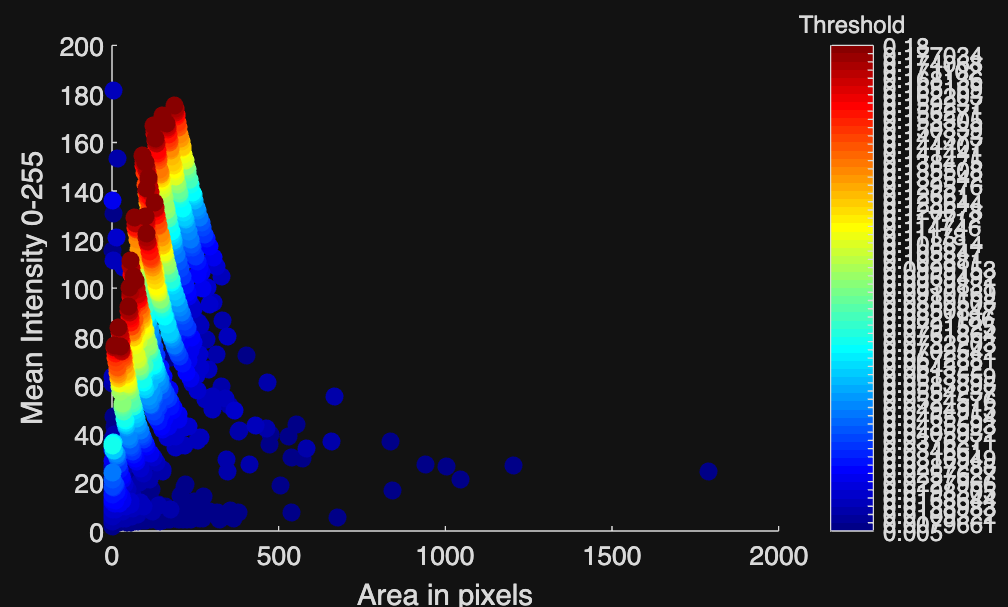

%% Plotting Mean Intensity vs Area
clf; hold on;
thresholds = linspace(0.005, 0.18, 60);
cm = jet(length(thresholds));
colormap(cm);

for i = 1:length(thresholds)
    % Binarize and get region properties
    bw_test = imbinarize(imgaussfilt(frgr_save, 1), thresholds(i));
    rp_test = regionprops(bw_test, greens_save, 'Centroid', 'Area', 'Eccentricity', 'MeanIntensity');
    
    % Extract properties
    areas = [rp_test.Area];
    mean_intensities = [rp_test.MeanIntensity];
    eccen = [rp_test.Eccentricity];
    
    % Plot areas vs max_intensities in Figure 1
    scatter(areas, mean_intensities, 45, cm(i,:), 'filled')
end

xlabel("Area in pixels");
ylabel("Mean Intensity 0-255");
cb=colorbar;
cb.Ticks = thresholds;
cb.TickLabels = num2cell(thresholds);
cb.Title.String = "Threshold";
set(gca,'CLim',[min(thresholds), max(thresholds)]);

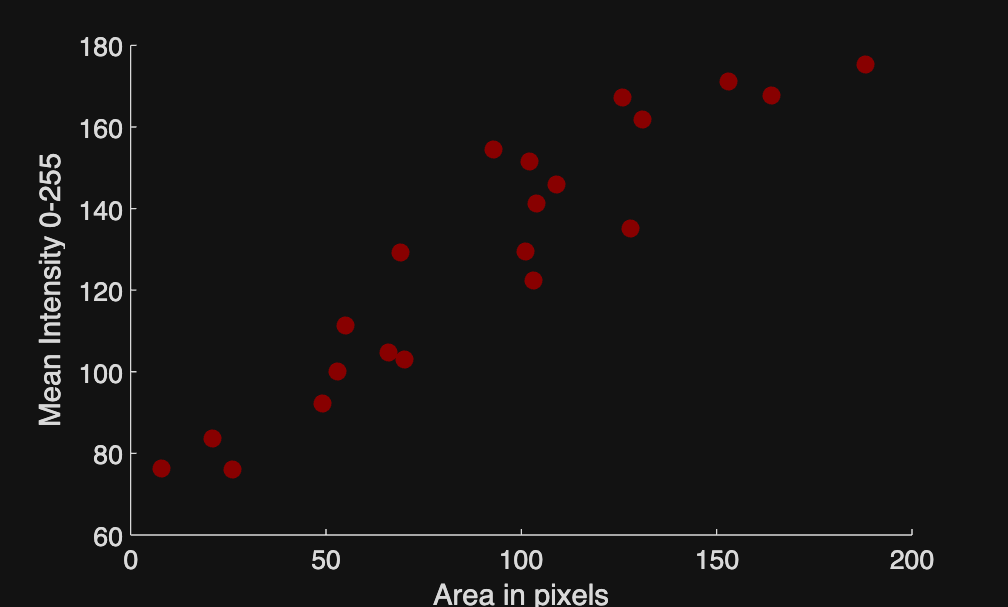

%% Plotting Mean Intensity vs Area
clf; hold on;
threshold = 0.18;
cm = jet(length(thresholds));
colormap(cm);

% Binarize and get region properties
bw_test = imbinarize(imgaussfilt(frgr_save, 1), threshold);
rp_test = regionprops(bw_test, greens_save, 'Centroid', 'Area', 'Eccentricity', 'MeanIntensity');

% Extract properties
areas = [rp_test.Area];
mean_intensities = [rp_test.MeanIntensity];
eccen = [rp_test.Eccentricity];

% Plot areas vs max_intensities in Figure 1
scatter(areas, mean_intensities, 45, cm(i,:), 'filled')


xlabel("Area in pixels");
ylabel("Mean Intensity 0-255");